# Lecture 2

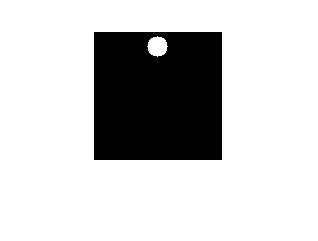

clear all;
clc;

a = zeros(128, 128);
for k = 1:128
    for l = 1:128
        x = l-15;
        y = k-64;
        c = x*x + y*y;  % x^2 + y^2 = 10^2
        if c<=100
            a(l,k)=1;
        end
    end
end
imshow(a);

## Vectorized circle

最終沒有想到一個比較好的方式，原本想用極座標的方式產生一個圓但失敗了(會變成矩形的)

以下是參考 [https://www.mathworks.com/matlabcentral/answers/346377-circle-in-a-matrix](https://www.mathworks.com/matlabcentral/answers/346377-circle-in-a-matrix) 中的做法

但產生出來的matrix會是logical的。

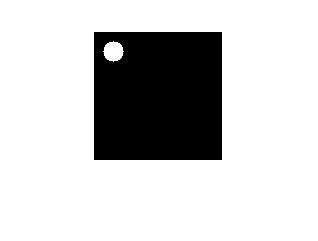

clear all;
clc;

a = zeros(128, 128);
one = ones(1, 128);
ord = 1:128;
col = one'*ord;
row = ord'*one;
r = 10;
xc = 20;
yc = 20;
circle = (row-yc).^2 + (col-xc).^2 <= r.^2;
imshow(circle)

## Before Vectorization

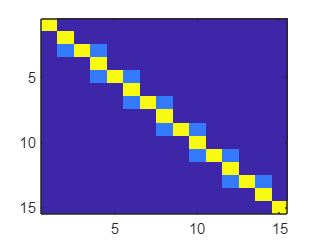

clear all;
clc;

u = eye(15, 15);
n = 13;m = 13;
omega = 0.5;
d = 0;
jb = 2; je = n+1; ib = 3; ie = m+1;
for i = ib:2:ie
    for j = jb:2:je
        up = (u(i, j+1) + u(i+1, j)+ ...
            u(i-1, j) + u(i, j-1))*0.25;
        u(i, j) = (1.0-omega)*u(i, j)+omega*up;
        d = d+abs(up-u(i, j));
    end
end
imagesc(u)

## After

clc;
clear all;
u = eye(15, 15);
n = 13;m = 13;
omega = 0.5;
d = 0;
jb = 2; je = n+1; ib = 3; ie = m+1;
i = ib:2:ie;
j = jb:2:je;
up = (u(i, j+1) + u(i+1, j)+u(i-1, j) + u(i, j-1))*0.25;
u(i, j) = (1.0-omega)*u(i, j)+omega*up;
d = d+abs(up-u(i, j));
imagesc(u)